# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Julia\RawData_new'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 1;
Deci.Proceed            = true;  
Deci.PCom               = true;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\Julia\ProcessedData'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {5};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {6};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[14 15 16] [41 42] [51 52] [31 34] [37 38] [22 23]};   
    Deci.DT.Locks      = [12 30 20];
    Deci.DT.Toi        = [-2 3]; 
    
    Deci.DT.Block.Start = {100};
    Deci.DT.Block.End = {101};
    Deci.DT.Block.Markers = [];

## 2. PreProcessing Steps

Deci.PP.HBP        = 1;                                                                         % Scalar,High-bandpass filter, in Hz.
Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []   ;
Deci.PP.Ocu = [];
Deci.PP.eog = {'TVEOG','BVEOG','LHEOG','RHEOG'};


## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];                                                                % Critical Time Period for trial rejection (Respective to first Lock and Last Lock)
Deci.Art.muscle     = [];                                                                       % if empty, use default muscle parameters
Deci.Art.eog        = [];                                                                       % if empty, use default eog parameters
Deci.Art.PostICAbpf = [];                                                                       % Post ICA broadband pass filter, if desired

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =false;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3]; 
Deci.Analysis.LocksTitle = {'Stim' 'Rsp' 'Fdb'};
Deci.Analysis.DownSample = 500;

Deci.Analysis.Conditions    = {[22] [23]};
Deci.Analysis.CondTitle     = {'Correct' 'Incorrect'};                                               

#### Time-Frequency Analysis

Deci.Analysis.Freq.do = true;
Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(1),log(80),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 
Deci.Analysis.Channels = {'FCz', 'Cz', 'CP3', 'CP4'};

Deci.Analysis.Var =false;
Deci.Analysis.Clean = true;

%Cross-Frequency Coupling

Deci.Analysis.CFC.do = true;
Deci.Analysis.CFC.chanlow =  [{'FCz' 'Cz' 'CP3' 'CP4'}];
Deci.Analysis.CFC.chanhigh = [{'FCz' 'Cz' 'CP3' 'CP4'}];
Deci.Analysis.CFC.latencyhigh = [-.2 1]; %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-.2 1];
Deci.Analysis.CFC.freqhigh = [12.5 80];
Deci.Analysis.CFC.freqlow = [4 8];
Deci.Analysis.CFC.keeptrials = 'no'

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 1
        Proceed: 1
           PCom: 1
             DT: [1×1 struct]
             PP: [1×1 struct]
            Art: [1×1 struct]
       Analysis: [1×1 struct]


Deci.Analysis.CFC.timebin = 1;
Deci.Analysis.CFC.method = 'mi';  % can only currently handle '' or 'mi'(pac)

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];


Extra

Deci.Analysis.Extra.QL.States = [20 21 23 24];
Deci.Analysis.Extra.QL.Actions = [31 32];
Deci.Analysis.Extra.QL.Reward  = [51 52];
Deci.Analysis.Extra.QL.Value  = {[20 10] [10 0] [0 -10] [-10 20]};

Deci.Analysis.Extra.do = false;
Deci.Analysis.Extra.list = [true];
Deci.Analysis.Extra.Functions = {'QL'};
Deci.Analysis.Extra.Params = {{Deci.Analysis.Extra.QL}};

## 5. Plotting

**General Set-Up**

Deci.Plot.Lock         = 'Fdb';                   % Which Lock to load                 
Deci.Plot.GrandAverage = true;                                   % Whether or not to grandaverage
Deci.Plot.FreqYScale   = 'linear';                   % Is the Frequency Y scale for Square plots on a linear or log scale?

% Comment your CondTitles here so you can refer to them for Math and Draw
%Deci.Analysis.CondTitle = {'Opt AB Corr' 'Opt CD Corr' 'Opt EF Corr' 'Opt GH Corr' ...
%                       'Opt AB Inc'  'Opt CD Inc' 'Opt EF Inc' 'Opt GH Inc' ...
%                       'Wst AB Corr' 'Wst CD Corr' 'Wst EF Corr' 'Wst GH Corr' ...
%                       'Wst AB Inc'  'Wst CD Inc' 'Wst EF Inc' 'Wst GH Inc'};

Deci.Plot.IndexTitle = {'Correct' 'Incorrect'};
Deci.Plot.Math         = {'x1 - x2'};           % Condition Math done after Bsl, Condition Indexes are appended on.
Deci.Plot.Draw         = {[1 2] [3]};                   % Cell array of Condition Index for each figure
Deci.Plot.Figures      = [true false];                             % Which figure to plot currently
Deci.Plot.Title        = {'Cor v Inc' 'Cor - Inc'};          % Title for each figure
Deci.Plot.Subtitle     = {{'Cor' 'Inc'} {'Cor - Inc'}};     % Cell array of strings of subtitles for each Condition

#### Time-Frequency

%Deci.Plot.Freq.Foi = [];
Deci.Plot.Freq.Foi = [4 8]

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 1
        Proceed: 1
           PCom: 1
             DT: [1×1 struct]
             PP: [1×1 struct]
            Art: [1×1 struct]
       Analysis: [1×1 struct]
           Plot: [1×1 struct]


Deci.Plot.Freq.Toi = [];
Deci.Plot.Freq.Channel = {'FCz'};
Deci.Plot.Freq.Type = 'ITPC';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Analysis.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxabs';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='none';    % Use 'absolute','relative','relchange','db','normchange'

Deci.Plot.Freq.Topo =1;
Deci.Plot.Freq.Square =1;

Deci.Plot.Freq.Wires.avg =  'freq';
Deci.Plot.Freq.Wires.errorbars = true ;

Deci.Plot.CFC.errorbars = true ;
Deci.Plot.CFC.chanlow =  [{'FCz' 'Cz' 'CP3' 'CP4'}];
Deci.Plot.CFC.chanhigh = [{'FCz' 'Cz' 'CP3' 'CP4'}];
Deci.Plot.CFC.freqhigh = 'beta';
Deci.Plot.CFC.freqlow = 'theta';
Deci.Plot.CFC.methods = {'mi'}

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 1
        Proceed: 1
           PCom: 1
             DT: [1×1 struct]
             PP: [1×1 struct]
            Art: [1×1 struct]
       Analysis: [1×1 struct]
           Plot: [1×1 struct]


Deci.Plot.CFC.Topo = false ;
Deci.Plot.CFC.Square = false ;
Deci.Plot.CFC.Hist = false ;
Deci.Plot.CFC.Wire = false ;
Deci.Plot.CFC.Phase = true ;
Deci.Plot.CFC.Spectrum = true ;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest


**ERP**

Deci.Plot.ERP.Toi = [];
Deci.Plot.ERP.Channel = {'FCz'};

Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time

Deci.Plot.ERP.Topo =0;
Deci.Plot.ERP.Wires =1;
Deci.Plot.ERP.errorbars =  true;

#### Behavioral

Deci.Plot.Behv = [];
% Deci.Plot.Behv.Source = 'Definition';
% 
% Deci.Plot.Behv.Acc.Total = {[1:16] [1:16]};
% Deci.Plot.Behv.Acc.Subtotal = {[1:8] [9:16]};
% Deci.Plot.Behv.Acc.Title = {'All Trials Percent' 'All Trials Percent'};
% Deci.Plot.Behv.Acc.Subtitle = {'Opt Percent' 'Wst Percent'};
% 
% Deci.Plot.Behv.Acc.Block = [1:6];
% Deci.Plot.Behv.Acc.Collapse.Trial =true;
% Deci.Plot.Behv.Acc.Collapse.Block = true;
% Deci.Plot.Behv.Acc.Collapse.Subject = true;
% Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
% Deci.Plot.Behv.Acc.Collapse.Movmean =  false;
% 
% Deci.Plot.Behv.RT.Draw = {[1:8] [9:16]};
% Deci.Plot.Behv.RT.Title = {'All Trials RT' 'All Trials Percent'};
% Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
% Deci.Plot.Behv.RT.Locks = [1 2];
% 
% Deci.Plot.Behv.RT.Block = [1:6];
% Deci.Plot.Behv.RT.Collapse.Trial =true;
% Deci.Plot.Behv.RT.Collapse.Block = true;
% Deci.Plot.Behv.RT.Collapse.Subject = true;
% Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =false;
Deci.Run.ERP =false;
Deci.Run.CFC = true;

## ** 6. Run**

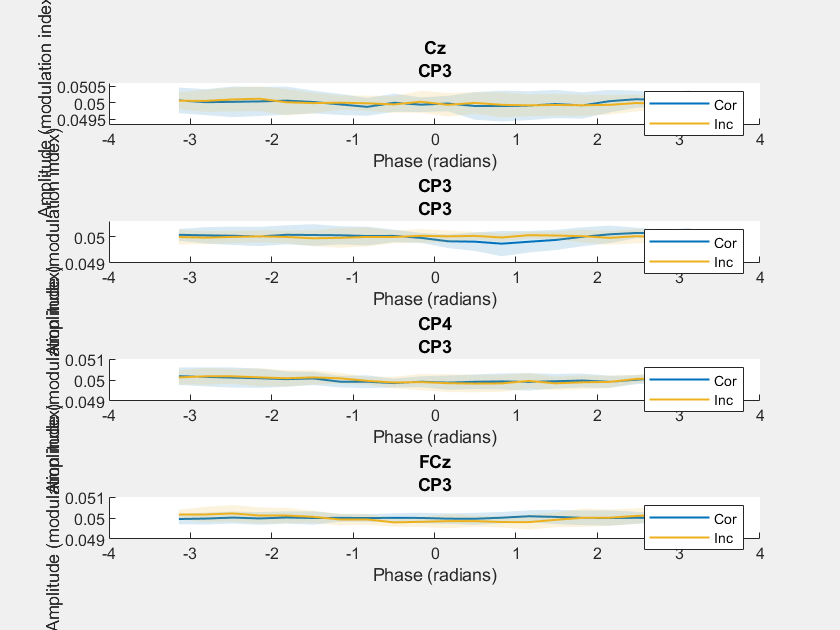

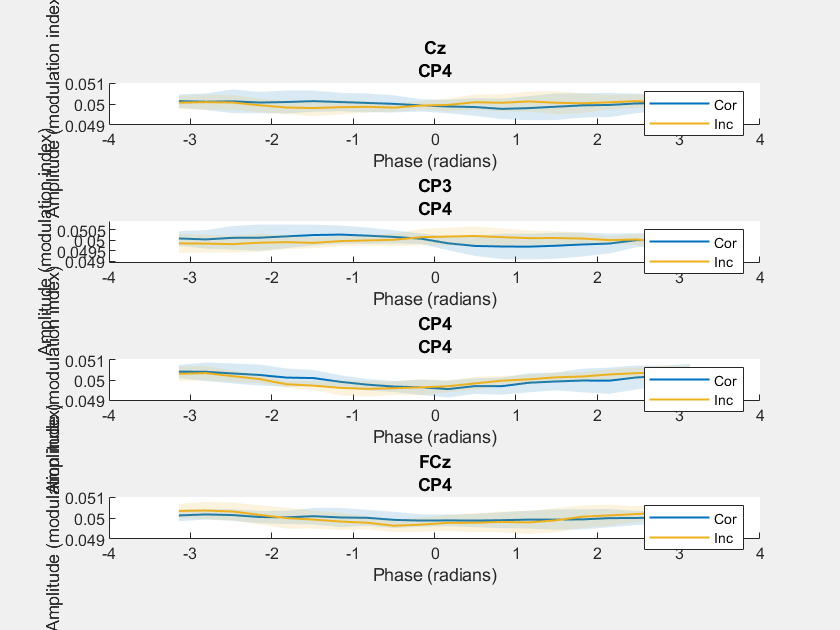

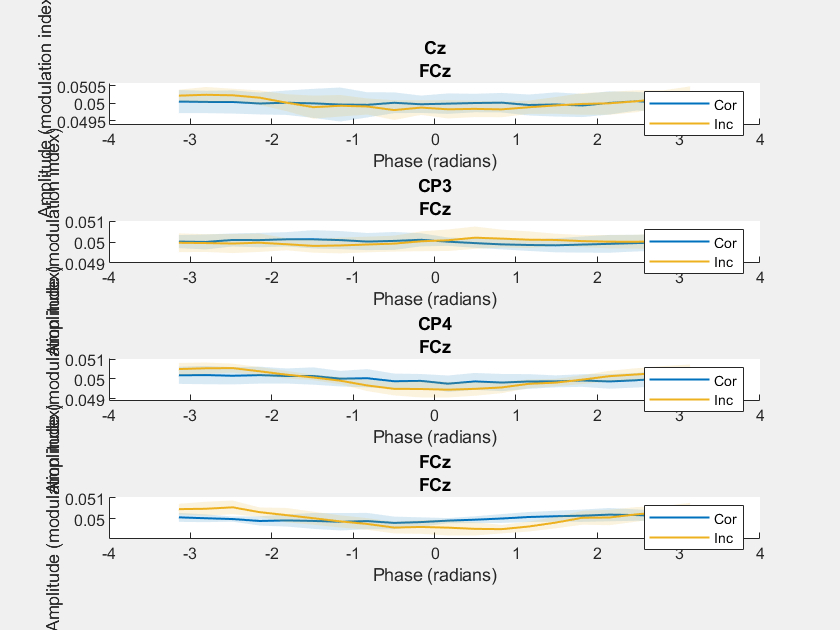

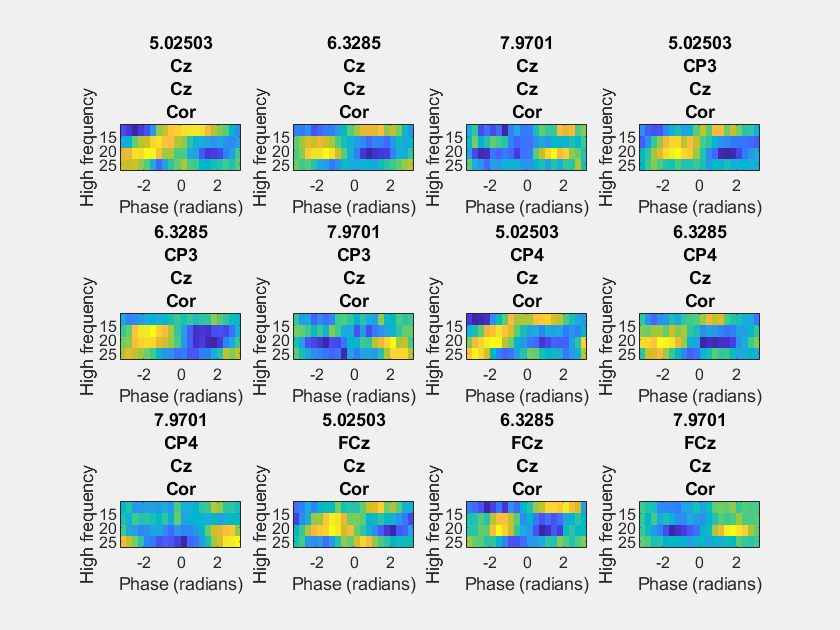

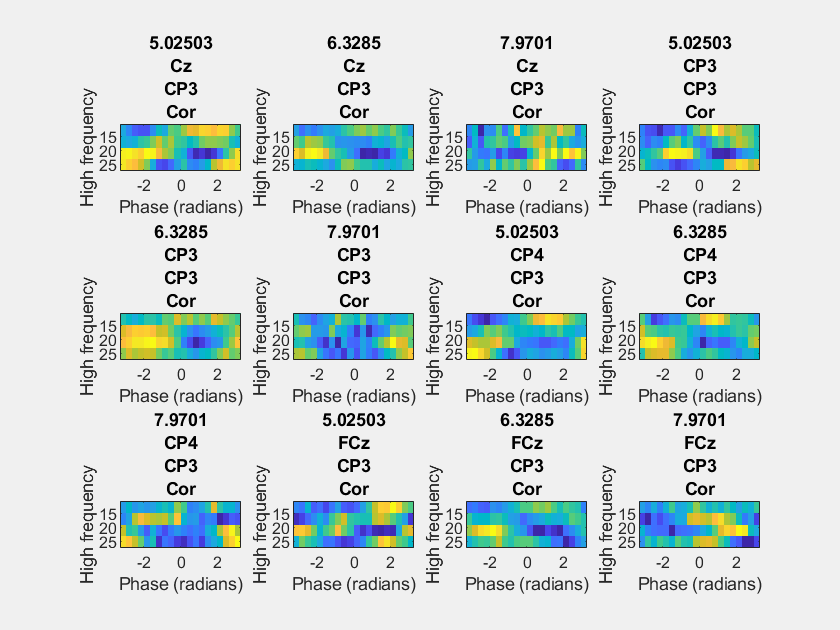

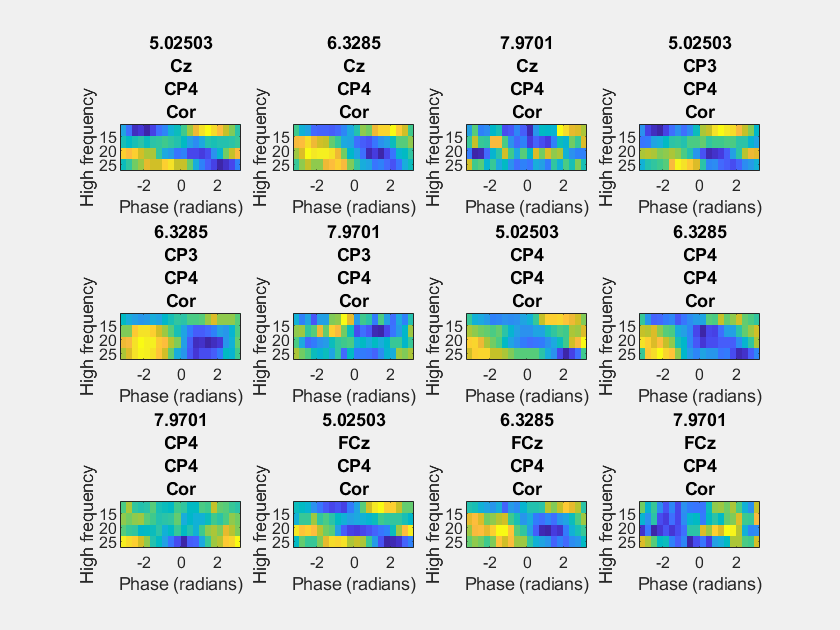

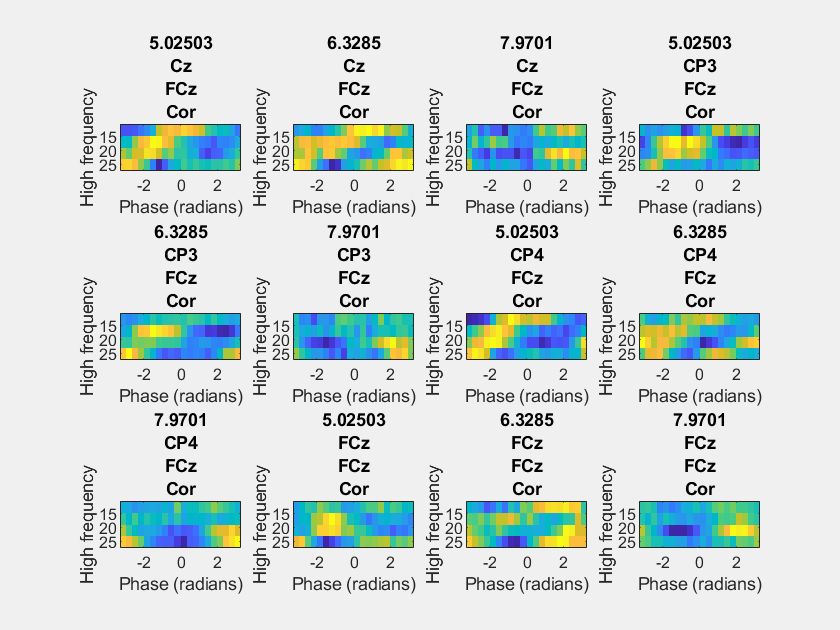

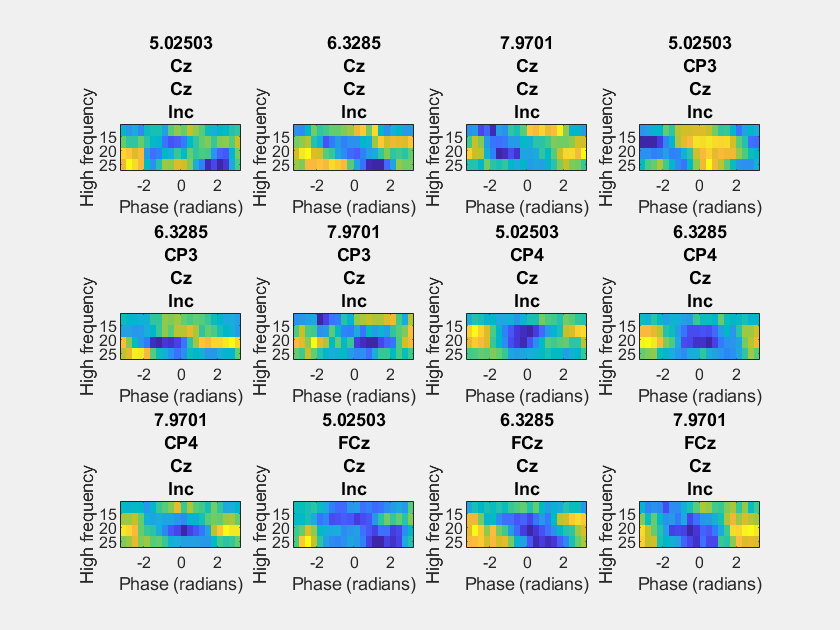


Deci_Backend(Deci);